%% Lab Flux Test Set-Point Calculations
%
% Lincoln Scheer
% 25 April 2024
%
%
% The purpose of this script is to determine MFC set-points that will
% simulate expected flux ranges in the lab environment.

clc, clear, close all

%% System Assumptions

% Chamber Surface Area
As = 0.064844702; % [m^2]

% Environment Assumptions
P = 101325; % [Pa]
T = 293.15; % [K]

% Expected Flux Ranges
F_l = 0.5; % low range [umol/m^2/s]
F_h = 10; % high range [umol/m^2/s]

% Delivery Tank Concentration
Ctank = 3003; % [ppm]

% MFC Size Used
MFC_q = 0.2; % [lpm]

% CO2 Ambient Concentration
Camb = 0; % [ppm]

% Pump Flow Rate
Q = 2; %[lpm]

% Resolution
res = 3;

% Unit Conversion Functions
ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);  % ppm to mol/m^3
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;    % mol/m^3 to ppm
lpm_to_cms = @(lpm) lpm/60000;              % liters per min to m^3 per min
cms_to_lpm = @(cms) cms*60000;              % m^3 per min to liters per min

% Chamber Concentration Steady State
Cchmb_tss = @(Camb, F, As, Q) Camb + (F.*As)./Q;

% Converting Flux Delivery from [umol/m^2/s] to [g/s]
w_F_l = F_l * 44.0095 * 1e-6 * As;
w_F_h = F_h * 44.0095 * 1e-6 * As; 

% Calculate Possible Setpoint Range % [m^3/s]
mfc_low = lpm_to_cms(MFC_q*0.1);
mfc_high = lpm_to_cms(MFC_q - MFC_q*0.1);
mfc_set_pt_rng = linspace(mfc_low, mfc_high, res);

% apply slpm to lpm conversion
load("mfc_q_calib.mat");

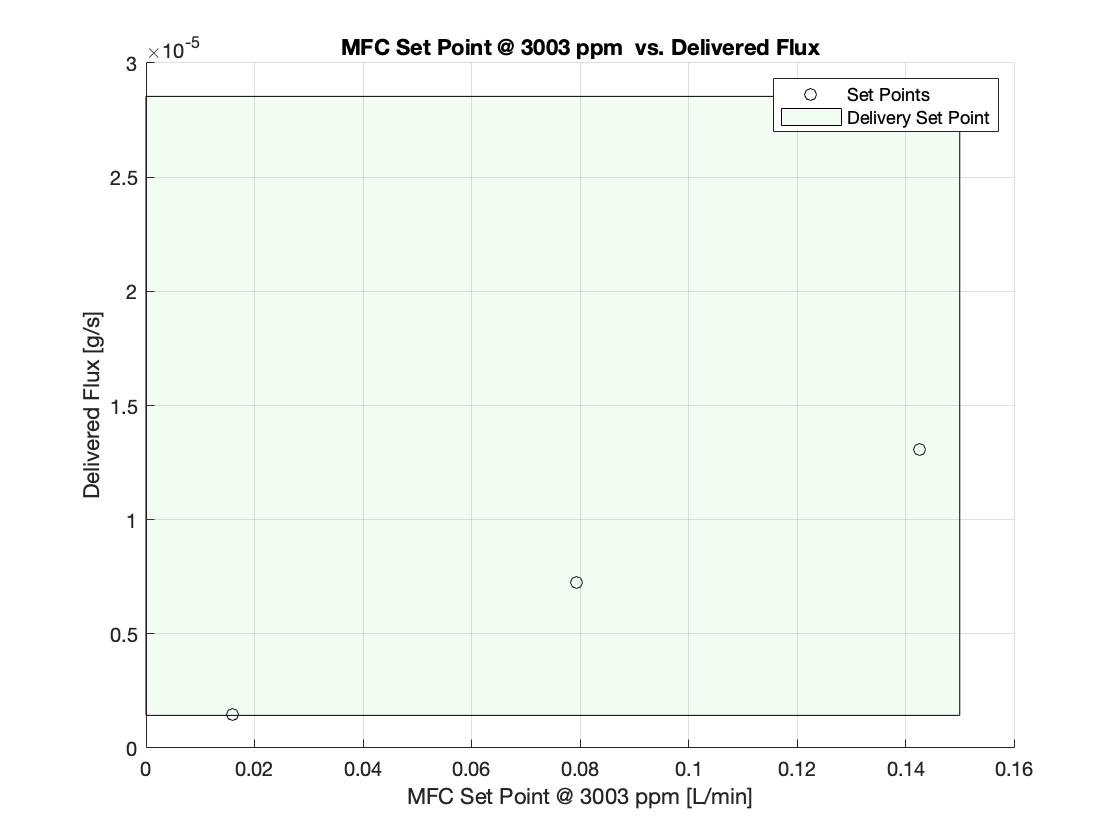

mfc_set_pt_rng = lpm_to_cms(cms_to_lpm( mfc_set_pt_rng )*0.7924+3e-5);

% Convert Tank Concentration from [ppm] to [g/m^3]
w_Ctank = ppm_to_mol(Ctank)*44.0096;

% Calculate Possible Delivery Range [g/s]
dlv_set_pt_rng = mfc_set_pt_rng * w_Ctank;

% Plotting Set Points vs. Delivered Flux
%
%   Green shaded area indicates desired delivered fluxes that we want, if
%   delivery set points are outside of green range, adjust the Ctank
%   concentration delivered or the MFC size used.
%
figure()
hold on
plot(cms_to_lpm(mfc_set_pt_rng), dlv_set_pt_rng, 'ko')
patch([min(xlim) max(xlim) max(xlim) min(xlim)], [w_F_l w_F_l w_F_h, w_F_h], [0.5 0.9 0.5], 'FaceAlpha', 0.1)
title("MFC Set Point @ " + Ctank + " ppm  vs. Delivered Flux")
legend(["Set Points", "Delivery Set Point"])
xlabel("MFC Set Point @ " + Ctank + " ppm [L/min]")
ylabel("Delivered Flux [g/s]")
grid on


% Creating Table
set_points = table(cms_to_lpm(mfc_set_pt_rng)', dlv_set_pt_rng', 'VariableNames', ["Set Point [sLPM]", "Delivered Flux [g/s]"]);
set_points.("Delivered Flux [g/day]") = (set_points.("Delivered Flux [g/s]")*60*60*24)/As;
set_points.("Delivered Flux [umol/m^2/s]") = ((set_points.("Delivered Flux [g/s]")./44.0095)./As)*1e6;
set_points.("Expected Chamber Steady State CO2 [ppm]") = mol_to_ppm(Cchmb_tss(ppm_to_mol(Camb), set_points.("Delivered Flux [umol/m^2/s]")*1e-6, As, lpm_to_cms(Q)))

set_points = 3×5 table
    Set Point [sLPM]    Delivered Flux [g/s]    Delivered Flux [g/day]    Delivered Flux [umol/m^2/s]    Expected Chamber Steady State CO2 [ppm]
    ________________    ____________________    ______________________    ___________________________    _______________________________________

        0.015878              1.454e-06                 1.9373                      0.5095                               23.841                 
         0.07927              7.259e-06                  9.672                      2.5436                               119.02                 
         0.14266             1.3064e-05                 17.407                      4.5778                               214.21                 


% Apply Calibration
%load('q_calib.mat');
%set_points.("Corrected Set Point [SLPM]") = predict(Q_actual, cms_to_lpm(mfc_set_pt_rng)');

Q_total = lpm_to_cms(Q);
Q_sp = mfc_set_pt_rng;
Q_am = Q_total - Q_sp;
Css = (Ctank*Q_sp+Camb*Q_am)/(Q_total);
fprintf("%.1f\t[ppm]\n", Css)

23.8	[ppm]
119.0	[ppm]
214.2	[ppm]
